% https://www.mathworks.com/matlabcentral/answers/1720245-hi-all-how-to-create-image-datasets-i-need-them-to-train-neural-networks-i-have-about-15-to-20

dataDir = '/cats';
% use image folder to get dataset
imds = imageDatastore(dataDir,'IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');
% use Alexnet to get cnn model
alex_net = alexnet;
class_number = length(unique(imds.Labels));
alex_net_share = alex_net.Layers(1:end-3);
alex_net_add = [
    fullyConnectedLayer(class_number,'Name','fc8','WeightLearnRateFactor',10, 'BiasLearnRateFactor',20)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classification')
    ];
layers_1 = [alex_net_share
    alex_net_add];
% train
augimdsTrain = augmentedImageDatastore([227 227],imdsTrain);
augimdsValidation = augmentedImageDatastore([227 227],imdsValidation);
miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false);
trainedNet = trainNetwork(augimdsTrain,layers_1,options);
% test
[YPred,probs] = classify(trainedNet,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.7069

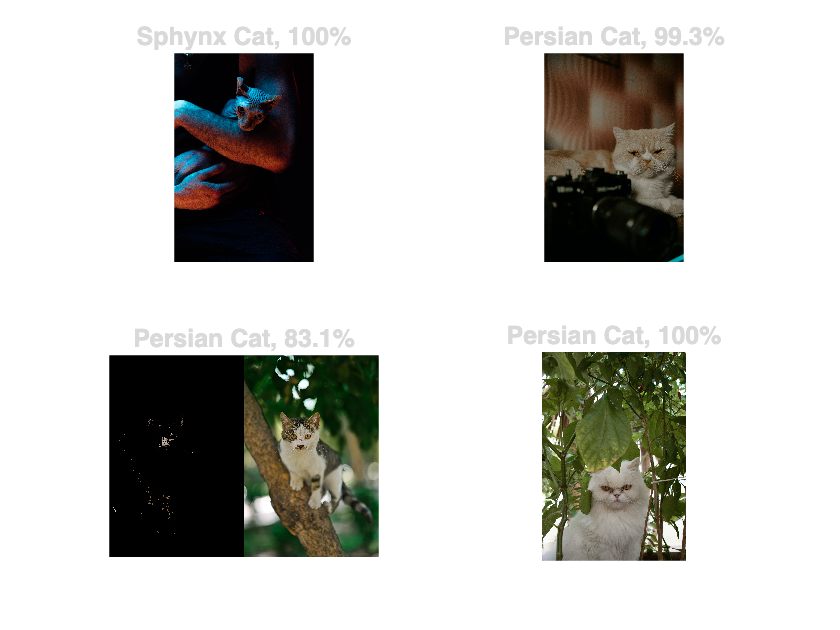

% app
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");

end

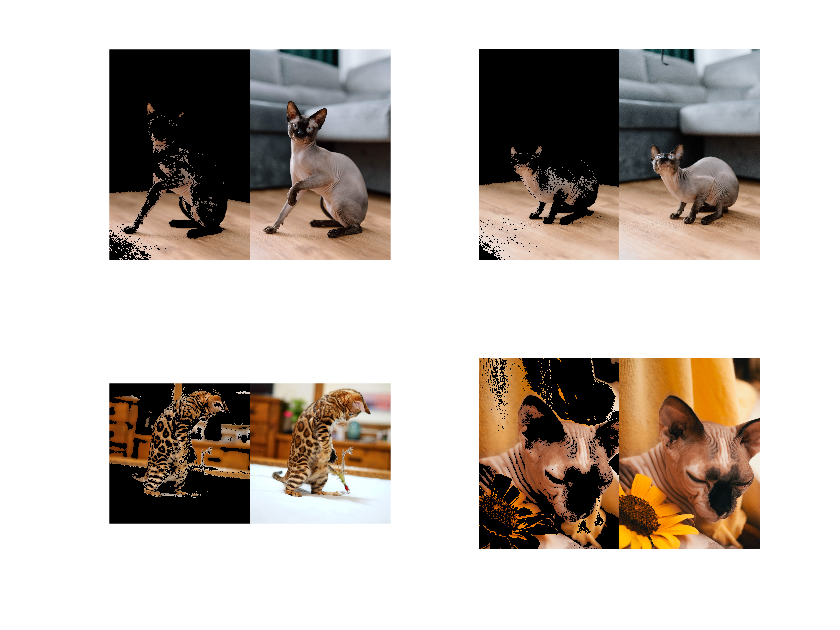

im = 4096×2731×3 uint8 array
im(:,:,1) =

   162   162   162   162   162   162   162   162   161   161   162   162   162   163   163   163   160   160   160   160   160   160   160   160   162   162   162   162   162   162   162   162   163   163   163   163   163   163   163   163   169   169   169   169   169   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170   170   170   176   175   174   172   171   169   168   167   173   173   174   174   175   175   175   175   173   173   173   173   174   174   175   175   174   174   174   174   175   175   176   176   174   174   174   174   174   174   174   174   175   175   176   176   176   177   177   177   179   180   181   182   183   182   182   181   183   181   179   181   184   187   187   187   184   184   184   184   184   184   184   184   184   184   184   185   185   186   186   186   189   189   189   189   189   189   189   189   190   190   191   191   191   192   192   1

path = '/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats'

ImOutFolder = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/catsDone"

file = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats/ctapplied1jpg"

im = 6000×4000×3 uint8 array
im(:,:,1) =

   164   165   166   166   165   162   159   157   162   161   161   160   159   158   158   157   161   162   163   164   164   164   163   163   155   156   158   161   163   166   168   169   163   170   170   162   161   168   167   160   169   169   169   169   169   169   170   170   174   173   171   169   168   166   165   164   167   168   169   169   168   166   162   160   172   172   170   169   167   165   164   163   171   170   169   169   168   167   166   167   164   166   167   169   171   173   175   175   167   168   170   171   171   170   167   166   167   167   168   169   171   172   172   172   173   171   171   170   170   171   173   175   176   176   177   176   175   174   172   171   175   175   174   174   173   173   172   172   178   172   172   178   178   172   172   178   180   178   176   174   173   174   176   177   180   180   180   179   178   178   177   177   177   177   177   177   177   178   178   1

path = '/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats'

ImOutFolder = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/catsDone"

file = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats/ctapplied2jpg"

im = 1219×1219×3 uint8 array
im(:,:,1) =

    24    25    24    24    25    26    25    27    27    27    27    27    25    26    28    26    26    28    28    29    29    28    29    27    27    27    27    27    27    28    29    28    29    28    29    31    31    28    28    29    30    30    30    29    30    31    30    30    30    30    31    31    30    30    28    29    29    29    29    30    27    26    27    26    27    26    27    28    28    27    26    26    27    27    28    27    27    26    26    25    28    27    27    28    27    26    26    26    28    28    27    27    28    27    26    28    27    28    28    28    29    28    28    28    29    28    29    28    27    27    27    28    28    27    29    31    28    27    28    28    30    29    27    26    27    28    27    27    26    26    27    26    26    27    27    27    25    25    26    27    26    27    27    26    27    28    26    25    26    26    25    27    27    28    27    27    26    27    26    

path = '/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats'

ImOutFolder = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/catsDone"

file = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats/ctapplied3jpg"

im = 5463×4000×3 uint8 array
im(:,:,1) =

   181   180   180   178   176   173   170   168   168   169   172   170   170   172   176   178   168   168   170   171   170   166   160   157   156   148   138   134   134   130   123   117   116   119   122   123   123   124   130   134   142   148   156   161   164   170   175   178   168   169   174   177   177   174   169   166   168   165   161   157   153   151   151   154   161   165   169   173   179   185   192   195   198   199   201   202   205   207   208   208   202   201   201   201   202   202   204   205   205   208   208   204   205   208   208   203   204   203   204   204   205   203   202   200   204   199   194   191   191   192   196   197   196   197   198   195   193   192   194   196   191   191   189   188   187   185   184   184   180   184   185   180   171   168   173   178   172   176   181   187   192   193   193   192   200   200   201   201   201   200   199   198   200   197   196   195   196   195   194   1

path = '/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats'

ImOutFolder = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/catsDone"

file = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats/ctapplied4jpg"

% app
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");

    im = I
    path = dataDir
    mask=createMask(im);
    segmentedImg = im .* uint8(repmat(mask, [1, 1, size(im, 3)]));
    imgcombined= [segmentedImg,im];
    imshow(imgcombined)
    ImOutFolder = "/catsDone"
    ImFileOut=fullfile(ImOutFolder, strcat('CTApplied',int2str(i),'.jpg'));
    file =  path + "/ctapplied" + i + "jpg"
    imwrite(imgcombined, path + "/ctapplied" + i + ".jpg" );

end

function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 06-Feb-2024
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.049;
channel1Max = 0.092;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.082;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.441;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
